# Lab02 

## Creation of the grid

At first, we create our Grid by using the function createGridWorld.

Then, we say which is the current state (in our case, it is [2,1]) and which case is the terminal one ([10, 10]). After this, we determinate which cells are going to be the obstacles. We chose those cells because of the jump rules which were given. 

GW = createGridWorld(10,10)

GW =   GridWorld with properties:

          GridSize: [10 10]
      CurrentState: "[1,1]"
            States: [100×1 string]
           Actions: [4×1 string]
                 T: [100×100×4 double]
                 R: [100×100×4 double]
    ObstacleStates: [0×1 string]
    TerminalStates: [0×1 string]


GW.CurrentState = '[2,1]';
GW.TerminalStates = '[10,10]';
GW.ObstacleStates = ["[2,8]";"[3,8]";"[4,8]";"[5,8]";"[5,9]";"[9,6]";"[9,7]";"[9,8]";"[9,9]";"[9,10]";"[9,2]";"[8,2]";"[7,2]";"[7,3]";"[7,4]";"[7,5]";"[7,6]"];

Now, we need to set the jump rule. Here, it is that we cans jump from cell [3,7] to cell [3,9] and from cell [8,9] to [10,9]. 

updateStateTranstionForObstacles(GW)
GW.T(state2idx(GW,"[3,7]"),:,:) = 0;
GW.T(state2idx(GW,"[3,7]"),state2idx(GW,"[3,9]"),:) = 1;

GW.T(state2idx(GW,"[8,9]"),:,:) = 0;
GW.T(state2idx(GW,"[8,9]"),state2idx(GW,"[10,9]"),:) = 1;

We can now define the different rewards.

nS = numel(GW.States);
nA = numel(GW.Actions);
GW.R = -1*ones(nS,nS,nA);
GW.R(state2idx(GW,"[3,7]"),state2idx(GW,"[3,9]"),:) = 3;
GW.R(state2idx(GW,"[8,9]"),state2idx(GW,"[10,9]"),:) = 5;
GW.R(:,state2idx(GW,GW.TerminalStates),:) = 15;

In order to create the grid environment, we use `rlMDPEnv`

env = rlMDPEnv(GW)

env =   rlMDPEnv with properties:

       Model: [1×1 rl.env.GridWorld]
    ResetFcn: []


Puis nous visualisions la grille!

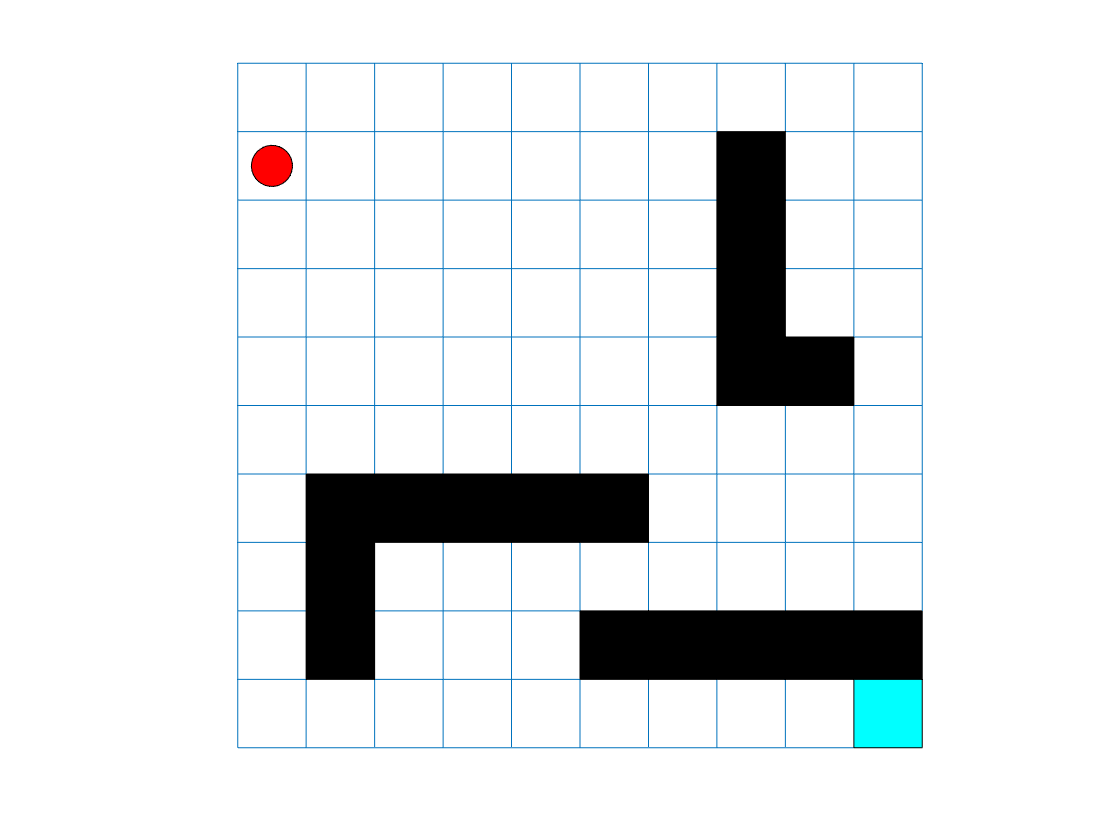

plot(env)

## Creation of the environment

Now that we have the grid, we create the basic world environment.